## **SIMULATION DATA**

% Load parameters
clear all
clc;

load('parameters.mat');

simul.select1 = 1;      % takes values in {1, 2} = {deg, rpm} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stair_gain = 1;   % takes values in {-1, 1}
simul.ramp_gain = 1;    % takes values in [0,1]
simul.stepdeg = 0;      % sets the step amplitude of the deg step

warning('off','all')

#### **[1.1] Positive stair simulation**

% Chose the correct simulation reference
simul.select1 = 2;
simul.select2 = 2;
simul.stair_gain = 1;

positive_stair = sim('lab0_sim_deg','StartTime','0','StopTime','45');

Found algebraic loop containing: 
lab0_sim_deg/PID/FIX  (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)
lab0_sim_deg/Quanser SR

Simulation aborted

save('positive_stair.mat','positive_stair')

#### **[1.2] Negative stair simulation**

% Chose the correct simulation reference
simul.select1 = 2;
simul.select2 = 2;
simul.stair_gain = -1;

negative_stair = sim('lab0_sim_deg','StartTime','0','StopTime','45');

Found algebraic loop containing: 
lab0_sim_deg/PID/FIX  (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)
lab0_sim_deg/Quanser SR

Simulation aborted

save('negative_stair.mat','negative_stair')

#### **[1.3] FRICTION ESTIMATION**

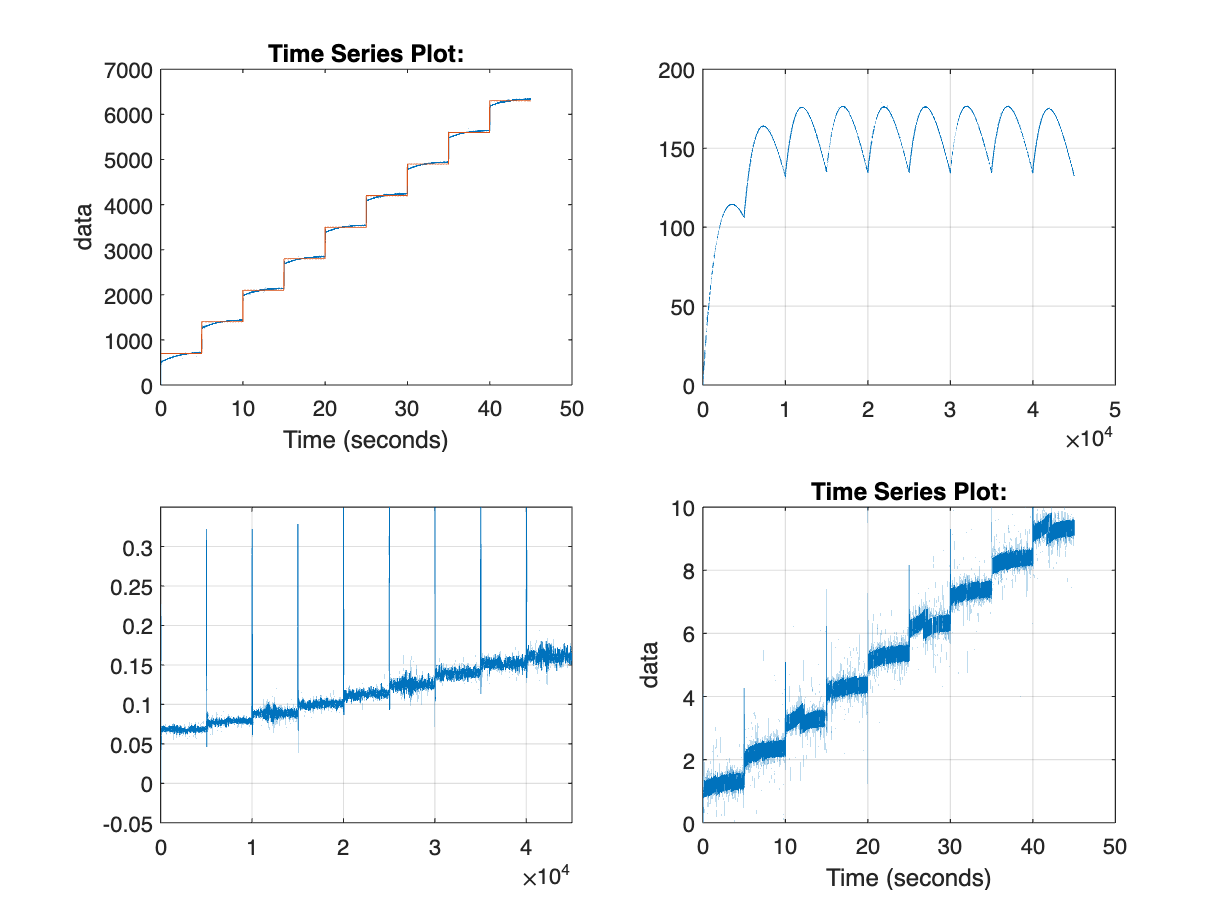

      Beq: 1.6515e-05
    tausf: 0.7629

   1.5693e-05   1.7336e-05
   7.1849e-01   8.0737e-01



run('Friction_estimation.mlx')

Initialization of all parameters that has been deleted

simul.select1 = 1;      % takes values in {1, 2} = {deg, rpm} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stair_gain = 1;   % takes values in {-1, 1}
simul.ramp_gain = 1;    % takes values in [0,1]
simul.stepdeg = 0;      % sets the step amplitude of the deg step

warning('off','all')

#### [2.1] Inertia estimation

simul.select1 = 2;      % rpm reference
simul.select2 = 3;      % stair reference

% Generate a vector that contains the estimate of Jeq for each run
% The final values correspond to its mean
% Set the numbers of experiments
simul.Nexp = 2;
Jeq.vals = zeros(simul.Nexp);

We run different simulation varing the ramp amplitude

simul.ramp_gain = 1;

for i = 1: simul.Nexp
    clear triang_ref
    clear est
    triang_ref = sim('lab0_sim_deg','StartTime','0','StopTime','20');

Found algebraic loop containing: 
lab0_sim_deg/PID/FIX  (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)
lab0_sim_deg/Quanser SR

    run("Inertia_estimation.mlx");
    load("Je.mat");
    Jeq.vals(i) = Jeq.est.Je
end

Jf = mean(Jeq.vals)